# Fill Missing Values with Unequal Spacing

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

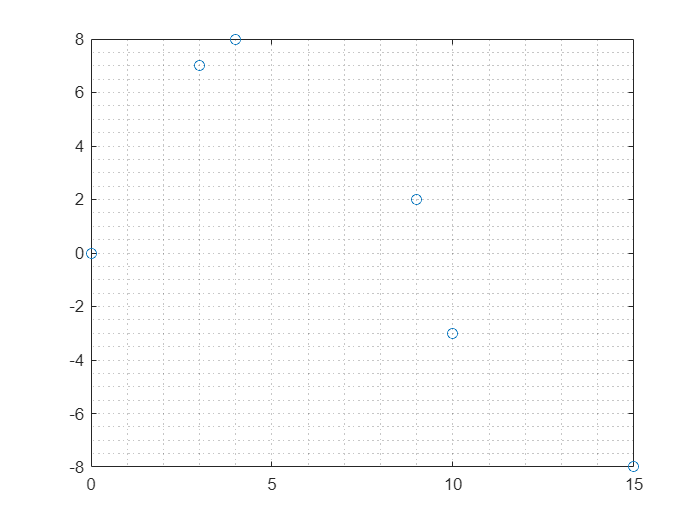

x = [0 2 3 4 7 9 10 12 15];
y = [0 NaN 7 8 NaN 2 -3 NaN -8];
plot(x, y, "o")
grid minor

## Task 1

By default, the `fillmissing` function assumes the observations are equally spaced when performing the interpolation.

z = fillmissing(y, "linear")

z =          0    3.5000    7.0000    8.0000    5.0000    2.0000   -3.0000   -5.5000   -8.0000


## Task 2

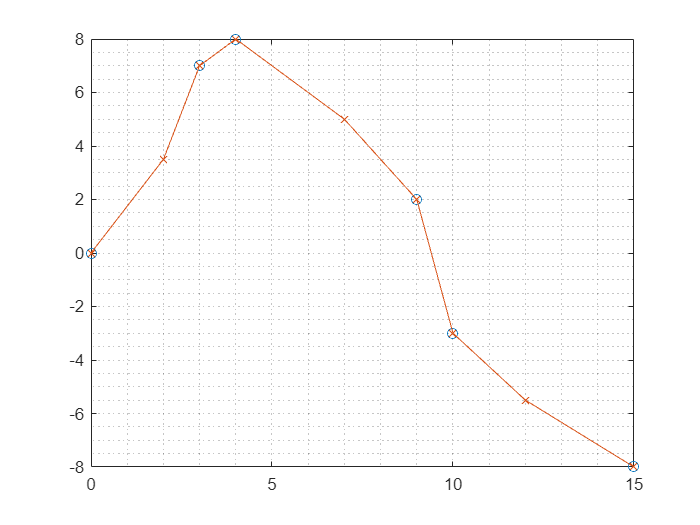

hold on
plot(x, z, "x-")
hold off

## Task 3

You can specify the spacing of the observations by providing a vector that represents the sampling locations:

`yinterp` `=` `fillmissing``(``y``,``"method"``,``...`

`"SamplePoints"``,``x``)`

z = fillmissing(y, "linear", "SamplePoints", x)

z =          0    4.6667    7.0000    8.0000    4.4000    2.0000   -3.0000   -5.0000   -8.0000


## Task 4

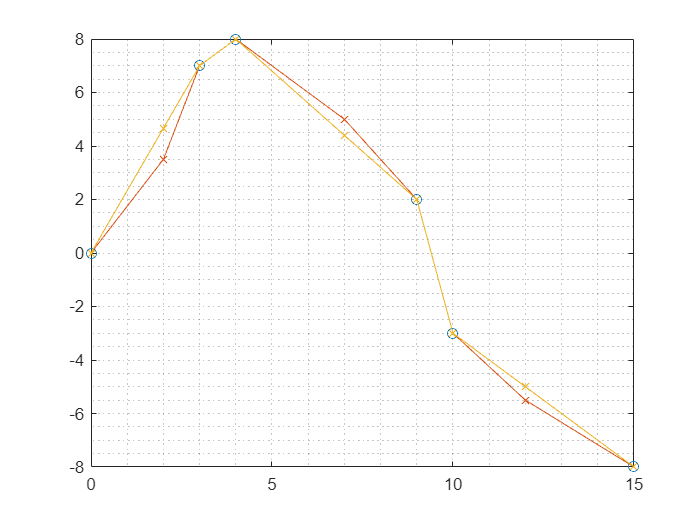

hold on
plot(x, z, "x-")
hold off